# Rectificador de Onda Completa RL Trifasico no Controlado

Este programa simula el comportamiento de un rectificador trifásico no controlado con una carga resistiva-inductiva (RL). Utilizando un conjunto de diodos que permiten la conducción en un solo sentido, proporcionando así un suministro eléctrico más estable y adecuado para diversas aplicaciones industriales.

En este proceso, los diodos se encargan de permitir el paso de la corriente en una sola dirección, lo que resulta en una forma de onda de salida pulsante. Esta configuración es especialmente útil en sistemas donde la variabilidad y las fluctuaciones de la corriente de entrada deben ser controladas para garantizar un funcionamiento eficiente.

**Aplicaciones**

Los rectificadores de onda completa trifásicos no controlados son ampliamente utilizados en aplicaciones industriales y comerciales, como en la alimentación de motores eléctricos, fuentes de alimentación de CC para dispositivos electrónicos, y en sistemas de carga de baterías.

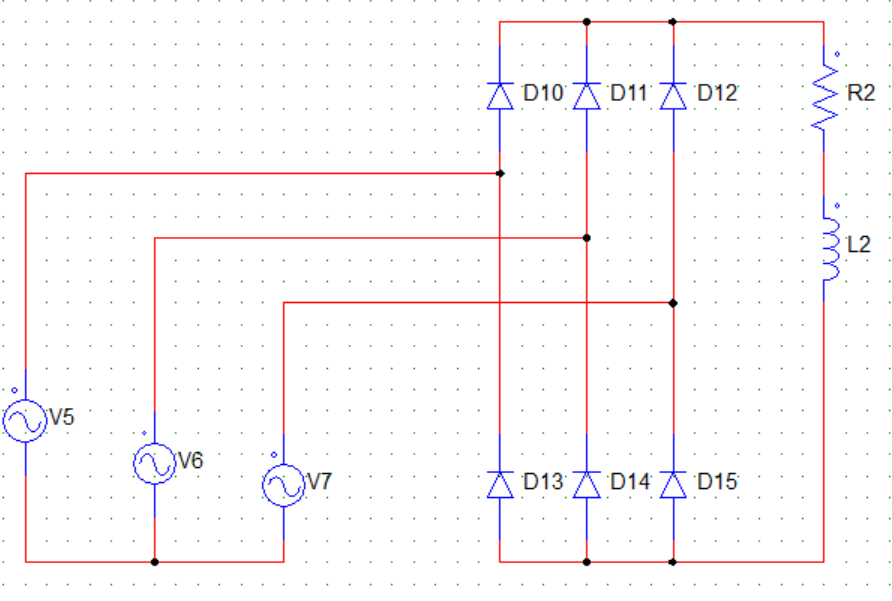

Como se observa rectificador de onda completa trifásico está compuesto por seis diodos dispuestos en un puente. Cada diodo se activa en diferentes momentos durante el ciclo de la señal de entrada, permitiendo que la corriente fluya hacia la carga en ambas mitades de la forma de onda.

El siguiente Livescript, tiene como finalidad realizar el analisis para cualquier parametro de entrada requerido, lo cual permite evaluar dinamicamente cualquier valor o cambio en los parametros de entrada, reflejados en sus parametros de salida.

A continuación se presenta una breve explicación de cómo funciona el livescript, además de las graficas a visualizar, las posibles mejoras y su desarrollo:

- Ingreso de parametros de entrada

- Visualización de los voltajes de fase

- Voltajes de línea:

- Grafica Io Vs Ifase

- Grafico Vout vs VST

Para el caso que se presenta el usuario debe ingresar los siguientes valores.

Vp:170

R: 10

L:0.01

f: 60

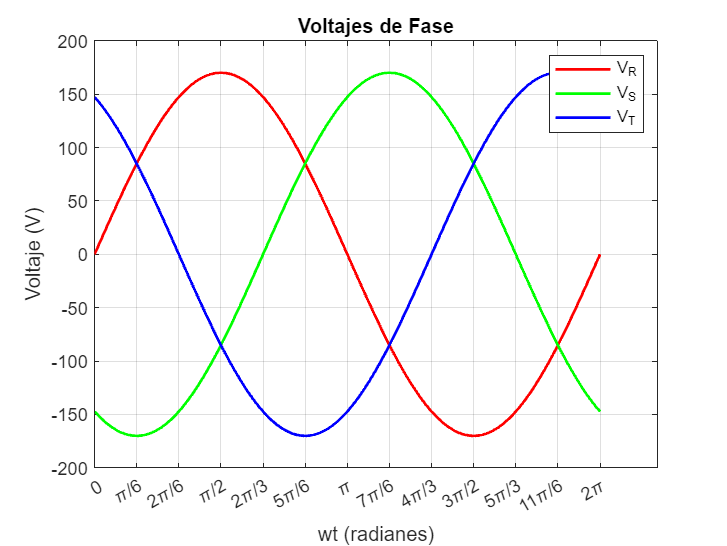

%% Parámetros del sistema para el rectificador trifásico no controlado
% Solicitar los valores de entrada
Vp = 170;    % Voltaje pico
R = 10;      % Resistencia
L = 0.000001;    % Inductancia
f = 60;      % Frecuencia

%% Definición de constantes
w = 2 * pi * f;               % Frecuencia angular
Z = sqrt(R^2 + (w * L)^2);     % Impedancia total
phi = atan(w * L / R);         % Ángulo de desfase debido a la inductancia

%% Definir las variables simbólicas para visualizar las funciones
syms wt

% Definir las funciones simbólicas para el voltaje y corriente
Vr_sym = Vp * sin(wt);          % Voltaje de fase R
Vs_sym = Vp * sin(wt - 2*pi/3); % Voltaje de fase S
Vt_sym = Vp * sin(wt + 2*pi/3); % Voltaje de fase T


% Voltajes de línea simbólicos
V_SR_sym = Vs_sym - Vr_sym;
V_RT_sym = Vr_sym - Vt_sym;
V_TS_sym = Vt_sym - Vs_sym;
V_RS_sym = Vr_sym - Vs_sym;
V_TR_sym = Vt_sym - Vr_sym;
V_ST_sym = Vs_sym - Vt_sym;

% Funciones simbólicas para voltaje y corriente
Io_wt = (sqrt(3) * Vp / Z) * (-cos(wt - phi) + ...
    exp(-(wt - (5*pi/6)) / (w * L / R)) * (sin(phi) / (1 - exp(-pi / (3 * tan(phi))))));

Vo_wt = sqrt(3) * Vp * (-cos(wt));


%% Cálculo numérico de los voltajes de entrada trifásicos en el tiempo (radianes)
wt_vals = linspace(0, 2*pi, 1000);    % Valores de tiempo en radianes
Vr_t = double(subs(Vr_sym, wt, wt_vals));  % Evaluar voltaje de fase R
Vs_t = double(subs(Vs_sym, wt, wt_vals));  % Evaluar voltaje de fase S
Vt_t = double(subs(Vt_sym, wt, wt_vals));  % Evaluar voltaje de fase T

% Voltajes de línea numéricos
V_SR = double(subs(V_SR_sym, wt, wt_vals));
V_RT = double(subs(V_RT_sym, wt, wt_vals));
V_TS = double(subs(V_TS_sym, wt, wt_vals));
V_RS = double(subs(V_RS_sym, wt, wt_vals));
V_TR = double(subs(V_TR_sym, wt, wt_vals));
V_ST = double(subs(V_ST_sym, wt, wt_vals));


%% Gráficas de los voltajes de fase
figure;
plot(wt_vals, Vr_t, 'r', 'LineWidth', 1.5); hold on;
plot(wt_vals, Vs_t, 'g', 'LineWidth', 1.5);
plot(wt_vals, Vt_t, 'b', 'LineWidth', 1.5);
grid on;
title('Voltajes de Fase');
xlabel('wt (radianes)');
ylabel('Voltaje (V)');
legend('V_R', 'V_S', 'V_T');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
 xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

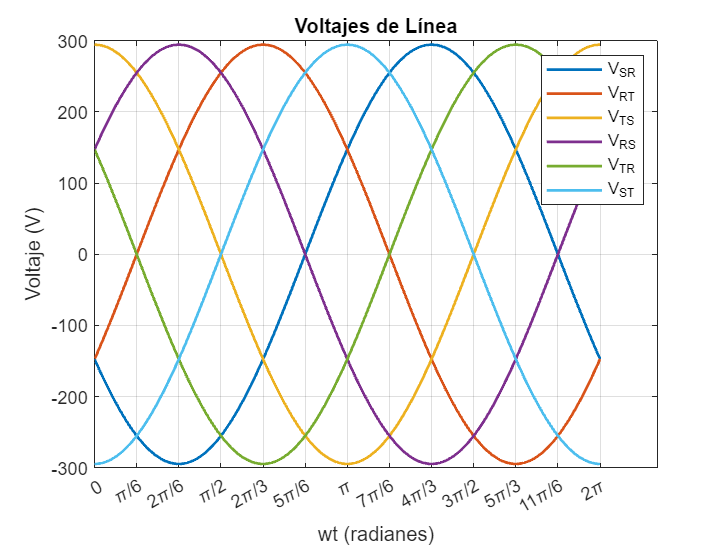


%% Gráficas de los voltajes de línea
figure;
plot(wt_vals, V_SR, 'LineWidth', 1.5); hold on;
plot(wt_vals, V_RT, 'LineWidth', 1.5);
plot(wt_vals, V_TS, 'LineWidth', 1.5);
plot(wt_vals, V_RS, 'LineWidth', 1.5);
plot(wt_vals, V_TR, 'LineWidth', 1.5);
plot(wt_vals, V_ST, 'LineWidth', 1.5);
grid on;
title('Voltajes de Línea');
xlabel('wt (radianes)');
ylabel('Voltaje (V)');
legend('V_{SR}', 'V_{RT}', 'V_{TS}', 'V_{RS}', 'V_{TR}', 'V_{ST}');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

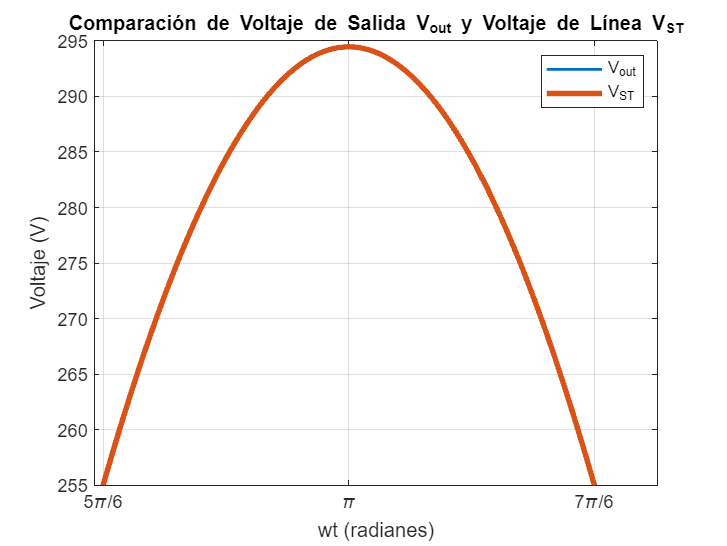



%% Evaluar las funciones simbólicas en el rango de interés
wt_vals = linspace(5*pi/6, 7*pi/6, 1000);  % Definir los valores de wt en radianes

%% Evaluación numérica del voltaje de salida Vo_wt y de V_ST
Vo_wt_num = double(subs(Vo_wt, wt, wt_vals));  % Convertir expresión simbólica en valores numéricos para Vo_wt
V_ST_num = double(subs(V_ST_sym, wt, wt_vals));  % Convertir expresión simbólica en valores numéricos para V_ST

%% Gráfica del voltaje de salida y voltaje V_ST
figure;
plot(wt_vals, Vo_wt_num, 'LineWidth', 1.5); hold on;
plot(wt_vals, V_ST_num, 'LineWidth', 3);  % Mayor trazo para V_ST
grid on;
title('Comparación de Voltaje de Salida V_{out} y Voltaje de Línea V_{ST}');
xlabel('wt (radianes)');
ylabel('Voltaje (V)');
legend('V_{out}', 'V_{ST}');
xticks([5*pi/6 pi 7*pi/6]);  % Ajuste de los ticks del eje x
xticklabels({'5\pi/6', '\pi', '7\pi/6'});

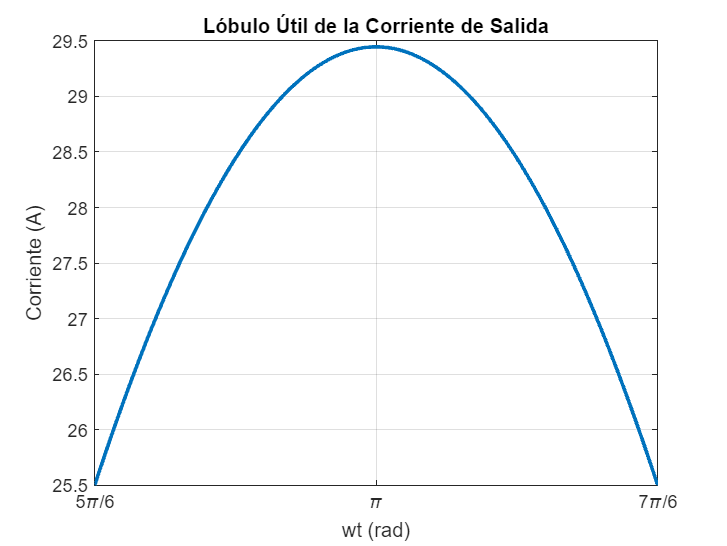



% Asegurarse de que la corriente sea positiva (ya que la corriente nunca es negativa en un rectificador)

% Evaluar I_out_values si es una expresión simbólica (suponiendo que I_out es una expresión simbólica)
I_out_values = double(subs(Io_wt, wt, wt_vals));  % Reemplaza 'I_out' con la expresión simbólica que tengas

% Graficar el lóbulo útil de la corriente de salida
figure;
plot(wt_vals, I_out_values, 'LineWidth', 2); 
xlabel('wt (rad)');
ylabel('Corriente (A)');
title('Lóbulo Útil de la Corriente de Salida');
grid on;
xlim([5*pi/6, 7*pi/6]);
xticks([5*pi/6 pi 7*pi/6]);
xticklabels({'5\pi/6', '\pi', '7\pi/6'});



%%Voltajes 
% Calcular la integral del voltaje desde 5π/6 hasta 7π/6
integral_Vo = int(Vo_wt, wt, 5*pi/6, 7*pi/6);

% Calcular el voltaje promedio
V_promedio_salida = (1 / (7*pi/6 - 5*pi/6)) * integral_Vo;


% Calcular la integral del cuadrado del voltaje instantáneo desde 5π/6 hasta 7π/6
integral_Vo_squared = int(Vo_wt^2, wt, 5*pi/6, 7*pi/6);

% Calcular el valor RMS
V_RMS = sqrt((1 / (7*pi/6 - 5*pi/6)) * integral_Vo_squared);

% Convertir los resultados simbólicos a numéricos
V_promedio_salida_num = double(V_promedio_salida);
nV_promedio_salida_num = double(V_promedio_salida_num);
disp(['Voltaje PROMEDIO de salida: ', num2str(V_promedio_salida_num), ' V']);

Voltaje PROMEDIO de salida: 281.1777 V



V_RMS_num = double(V_RMS);

% Mostrar los resultados importantes

nV_RMS_num = double(V_RMS_num);
disp(['Voltaje RMS de salida: ', num2str(V_RMS_num), ' V']);

Voltaje RMS de salida: 281.4252 V




%% Paso 2: Cálculo de la integral de la corriente cuadrada (para RMS)
integral_Io_squared = int(Io_wt^2, wt, 5*pi/6, 7*pi/6);

% Evaluación numérica de la integral
integral_Io_squared_val = double(integral_Io_squared);

%% Paso 4: Cálculo de la corriente RMS de salida

I_RMS_salida = sqrt((1 / (7*pi/6 - 5*pi/6)) * integral_Io_squared_val);
nI_RMS_salida = double(I_RMS_salida);
disp(['Corriente RMS de salida: ', num2str(I_RMS_salida), ' A']);

Corriente RMS de salida: 28.1425 A



%% Paso 5: Cálculo de la corriente promedio de salida

integral_Io = int(Io_wt, wt, 5*pi/6, 7*pi/6);
I_promedio_salida = (1 / (7*pi/6 - 5*pi/6)) * double(integral_Io);
nI_promedio_salida = double(I_promedio_salida);
disp(['Corriente promedio de salida: ', num2str(I_promedio_salida), ' A']);

Corriente promedio de salida: 28.1178 A



%% Paso 6: Cálculo de la corriente RMS de la fase R

I_R_RMS = sqrt(2/3) * I_RMS_salida;
nI_R_RMS = double(I_R_RMS);
disp(['Corriente RMS de la fase R: ', num2str(I_R_RMS), ' A']);

Corriente RMS de la fase R: 22.9783 A



syms x;  % Definir x como variable simbólica

%% Cálculo de los coeficientes a1 y b1 para el cálculo del THD
% Expresiones para b1
expr_b1_1 = (sqrt(3) * Vp / Z) * (-cos(x + (2 * pi / 6) - phi) + exp(-(x + (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);
expr_b1_2 = (sqrt(3) * Vp / Z) * (-cos(x + (4 * pi / 6) - phi) + exp(-(x + (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);
expr_b1_3 = (sqrt(3) * Vp / Z) * (-cos(x - (2 * pi / 6) - phi) + exp(-(x - (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);
expr_b1_4 = (sqrt(3) * Vp / Z) * (-cos(x - (4 * pi / 6) - phi) + exp(-(x - (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);

% Calcular las integrales para b1
b1_1 = (1 / pi) * int(expr_b1_1, x, 3 * pi / 6, 5 * pi / 6);
b1_2 = (1 / pi) * int(expr_b1_2, x, pi / 6, 3 * pi / 6);
b1_3 = (1 / pi) * int(expr_b1_3, x, 7 * pi / 6, 9 * pi / 6);
b1_4 = (1 / pi) * int(expr_b1_4, x, 9 * pi / 6, 11 * pi / 6);

% Sumar y restar los términos para obtener b1
b1 = double(b1_1 + b1_2 - b1_3 - b1_4);
nb1 = double(b1);
disp(['Coeficiente b1: ', num2str(b1)]);

Coeficiente b1: 31.0589



% Expresiones para a1
expr_a1_1 = (sqrt(3) * Vp / Z) * (-cos(x + (2 * pi / 6) - phi) + exp(-(x + (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);
expr_a1_2 = (sqrt(3) * Vp / Z) * (-cos(x + (4 * pi / 6) - phi) + exp(-(x + (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);
expr_a1_3 = (sqrt(3) * Vp / Z) * (-cos(x - (2 * pi / 6) - phi) + exp(-(x - (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);
expr_a1_4 = (sqrt(3) * Vp / Z) * (-cos(x - (4 * pi / 6) - phi) + exp(-(x - (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);

% Calcular las integrales para a1
a1_1 = (1 / pi) * int(expr_a1_1, x, 3 * pi / 6, 5 * pi / 6);
a1_2 = (1 / pi) * int(expr_a1_2, x, pi / 6, 3 * pi / 6);
a1_3 = (1 / pi) * int(expr_a1_3, x, 7 * pi / 6, 9 * pi / 6);
a1_4 = (1 / pi) * int(expr_a1_4, x, 9 * pi / 6, 11 * pi / 6);

% Sumar y restar los términos para obtener a1
a1 = double(a1_1 + a1_2 - a1_3 - a1_4);
na1 = double(a1);
disp(['Coeficiente a1: ', num2str(a1)]);

Coeficiente a1: -0.00011085



% Cálculo de I1_RMS (primer armónico)
I1_RMS = sqrt((b1^2 + a1^2)) / sqrt(2);
nI1_RMS = double(I1_RMS);
disp(['Primer armónico I1_RMS: ', num2str(I1_RMS), ' A']);

Primer armónico I1_RMS: 21.9619 A



%% Cálculo del THD (Distorsión Armónica Total)
THD = sqrt((I_R_RMS^2 / I1_RMS^2) - 1);
nTHD = double(THD);
disp(['THD: ', num2str(THD * 100), ' %']);

THD: 30.7725 %






%%POTENCIA APARENTE

S1 = nV_RMS_num * nI1_RMS;   % Potencia aparente sin armónicos

% Potencia activa (P)
P = S1 * cos(phi);  % Potencia activa

% Potencia reactiva (Q)
Q = S1 * sin(phi);  % Potencia reactiva

% Potencia aparente total (S) con THD
S = nV_RMS_num * nI1_RMS * sqrt(1 + nTHD^2);

% Potencia distorsionante (D)
D = sqrt(S^2 - S1^2);

%% Factor de potencia
% Factor de potencia de desplazamiento (cos φ)
FP_desplazamiento = cos(phi);

% Factor de potencia de distorsión
FP_distorsion = 1 / sqrt(1 + nTHD^2);  % Usar THD en lugar de THD_I

% Factor de potencia total
FP_total = FP_desplazamiento * FP_distorsion;

%% Mostrar resultados
disp(['Potencia aparente sin armónicos (S1): ', num2str(S1), ' VA']);

Potencia aparente sin armónicos (S1): 6180.6467 VA


disp(['Potencia activa (P): ', num2str(P), ' W']);

Potencia activa (P): 6180.6467 W


disp(['Potencia reactiva (Q): ', num2str(Q), ' VAR']);

Potencia reactiva (Q): 0.233 VAR


disp(['Potencia aparente total (S): ', num2str(S), ' VA']);

Potencia aparente total (S): 6466.6661 VA


disp(['Potencia distorsionante (D): ', num2str(D), ' VA']);

Potencia distorsionante (D): 1901.9402 VA


disp(['Factor de potencia de desplazamiento: ', num2str(FP_desplazamiento)]);

Factor de potencia de desplazamiento: 1


disp(['Factor de potencia de distorsión: ', num2str(FP_distorsion)]);

Factor de potencia de distorsión: 0.95577


disp(['Factor de potencia total: ', num2str(FP_total)]);

Factor de potencia total: 0.95577



%%FF
%% Potencia disipada por la resistencia
I_total_RMS = I1_RMS * sqrt(1 + THD^2);  % Corriente RMS total con THD
P_disipada = I_total_RMS^2 * R;  % Potencia disipada por la resistencia

%% Cálculo del factor de forma
Factor_de_forma = I_total_RMS / I_promedio_salida;
disp(['Factor de potencia total (FP_total): ', num2str(FP_total)]);

Factor de potencia total (FP_total): 0.95577


disp(['Potencia disipada por la resistencia: ', num2str(P_disipada), ' W']);

Potencia disipada por la resistencia: 5280.0108 W


disp(['Factor de forma: ', num2str(Factor_de_forma)]);

Factor de forma: 0.81722
